# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer = 1.0e+05 *

    8.1009    8.0919    8.0993    8.0997    8.1064    8.0991    8.1037    8.0938    8.1035    8.0996    8.1001    8.0949    8.1056    8.1071    8.0964    8.0895    8.0993    8.0928    8.0991    8.1015    8.0877    8.0924    8.0946    8.1021    8.1006    8.0840    8.1043    8.1092    8.1051    8.1125    8.0917    8.1001    8.0885    8.0978    8.0961    8.0940    8.0931    8.1107    8.0918    8.0938    8.1035    8.1027    8.1056    8.0969    8.1030    8.1012    8.0931    8.0850    8.0978    8.0961
    0.0111    0.0205   -0.0074   -0.0056   -0.0118    0.0263   -0.0039    0.0219   -0.0114    0.0290    0.0135   -0.0237   -0.0035    0.0010   -0.0169    0.0021    0.0253    0.0007   -0.0278   -0.0325    0.0193   -0.0174   -0.0108    0.0165    0.0021   -0.0111   -0.0337    0.0110    0.0234   -0.0012   -0.0215    0.0210   -0.0111   -0.0071   -0.0126   -0.0263    0.0124    0.0049    0.0007   -0.0046    0.0202    0.0128    0.0190   -0.0087   -0.0313   -0.0066    0.0303   -0.011

Nbuffer_variables = 28

Nsamples = 21000

Ninputs = 22

Noutputs = 5

ans =           22       21000


ans =            5       21000


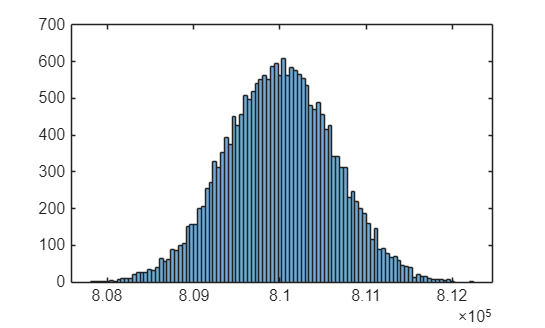

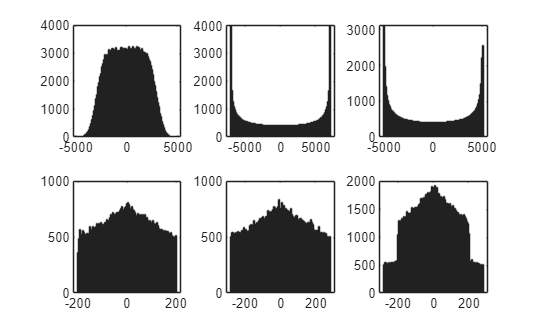

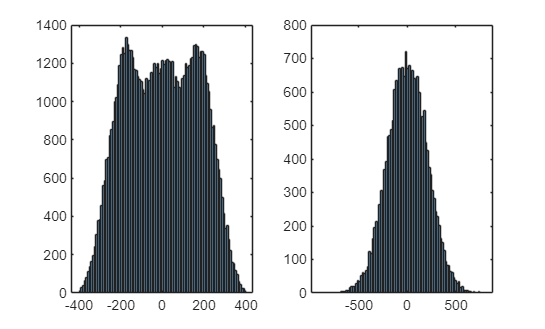

ans = 159.3418

ie_max = 396.1597

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 6000

C = 0.0050

vc_mean_ref = 18000

Xmax = 1.0e+05 *

    8.9100
    0.0714
    0.0714
    0.0714
    0.0714
    0.0714
    0.0714
    0.0714
    0.0714
    0.0714
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550


Ymax =          500
         500
         500
         500
        6000


Ninputs = 22

Nsamples = 21000

Noutputs = 5

Nsamples = 21000

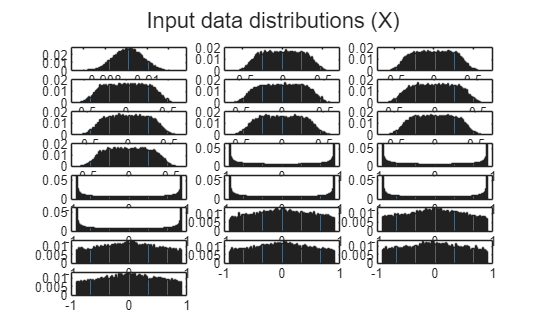

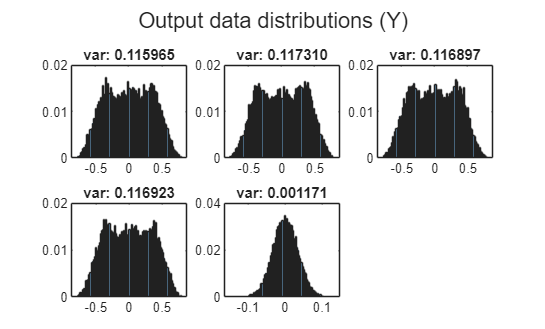

run('DataPreparation.mlx');

save_net = true; % Overwrite current feedforward architecture

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 3*Ninputs;
argsFFNN.HiddenActivation = 'relu';
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

FFnet = FFNNgenerator(argsFFNN)

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:4));
var_o = output_variance(5);
ErrorWeights = [ones(4, 1); var_e/var_o]

ErrorWeights =     1.0000
    1.0000
    1.0000
    1.0000
   99.7465



argsFFNNtrain                     = struct();
argsFFNNtrain.net                 = FFnet;
argsFFNNtrain.X_tr                = dlX_tr;
argsFFNNtrain.Y_tr                = dlY_tr;
argsFFNNtrain.X_val               = dlX_val;
argsFFNNtrain.Y_val               = dlY_val;
argsFFNNtrain.InitialLearningRate = 1e-2;
argsFFNNtrain.FinalLearningRate   = 1e-6;
argsFFNNtrain.Plots               = 'training-progress'

argsFFNNtrain = struct with fields:
                    net: [1×1 dlnetwork]
                   X_tr: [22×20000 dlarray]
                   Y_tr: [5×20000 dlarray]
                  X_val: [22×1000 dlarray]
                  Y_val: [5×1000 dlarray]
    InitialLearningRate: 0.0100
      FinalLearningRate: 1.0000e-06
                  Plots: 'training-progress'


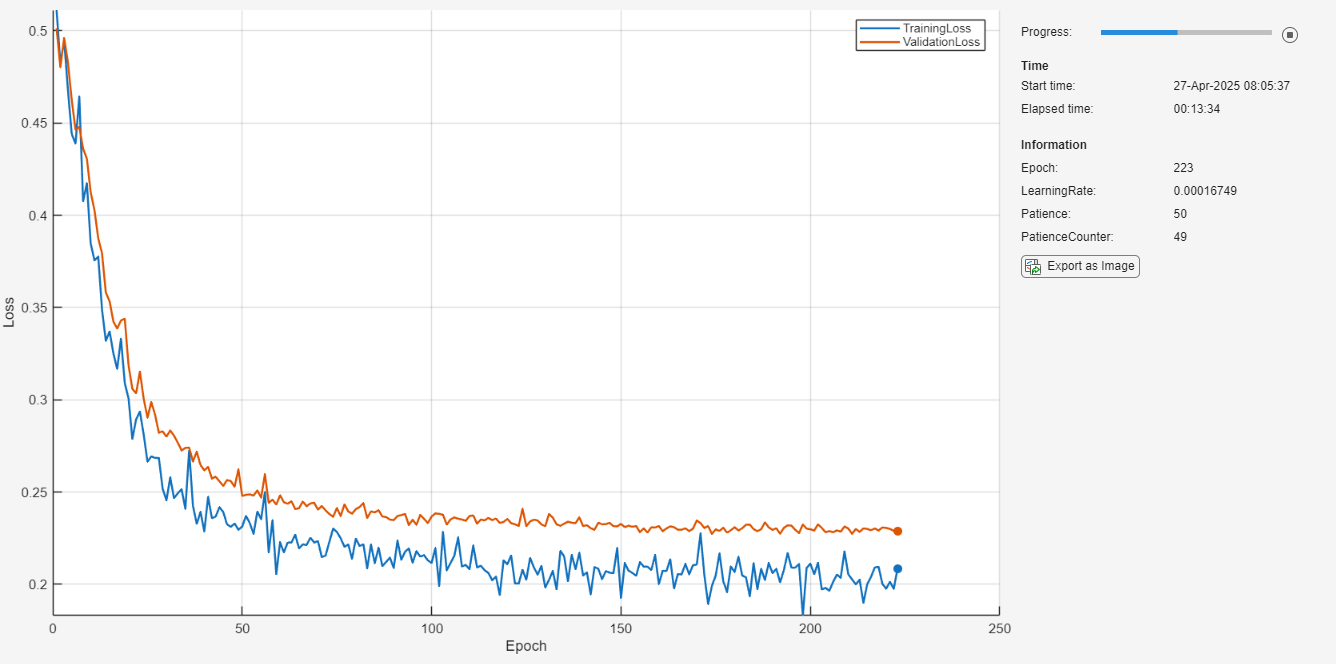

Early stopping at epoch 224: no improvement after 50 epochs.


FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


argsFFNNtrain.Verbose             = false;
argsFFNNtrain.MaxEpochs           = 500;
argsFFNNtrain.MiniBatchSize       = 128; % This could be adaptive during training for better fitting and generalization
argsFFNNtrain.ValidationPatience  = 50;
argsFFNNtrain.HuberThreshold      = 1;
argsFFNNtrain.ErrorWeights        = ErrorWeights;

FFnet = FFNNtrain(argsFFNNtrain, 'custom')


if save_net
    save('ImitationLearning\ActualArchitecture\FFnet.mat', "FFnet")
end

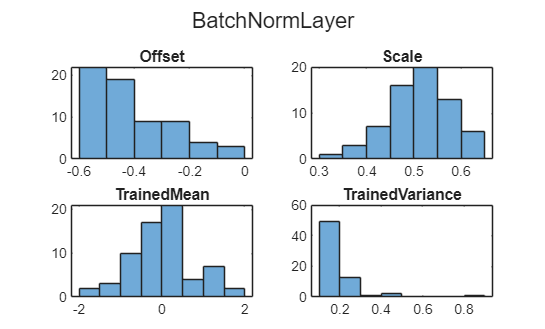

figure
subplot(2, 2, 1)
histogram(FFnet.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(FFnet.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(FFnet.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(FFnet.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, FFnet, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, FFnet, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.20572


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.22733


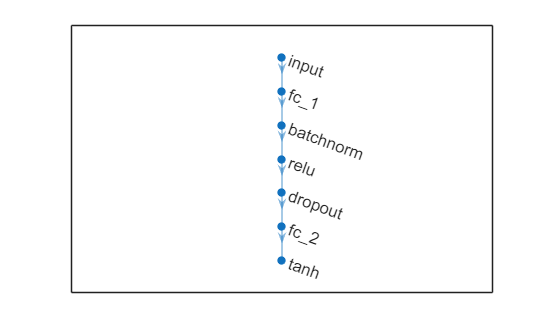


figure
plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)


   Initialized: true

   Number of learnables: 1.9k

   Inputs:
      1   'input'   22 features



# Performance analysis

## Complete timeseries

% pred = extractdata(FFnet.predict(dlX));
% figure
% subplot(ceil(Noutputs/3), 3, 1)
% stairs(1:Nsamples, Y(1, :))
% hold on
% stairs(1:Nsamples, pred(1, :))
% hold off
% for idx = 2:Noutputs
%     subplot(ceil(Noutputs/3), 3, idx)
%     stairs(1:Nsamples, Y(idx, :))
%     hold on
%     stairs(1:Nsamples, pred(idx, :))
%     hold off
% end
% sgtitle('Complete timeseries');

## Error histogram

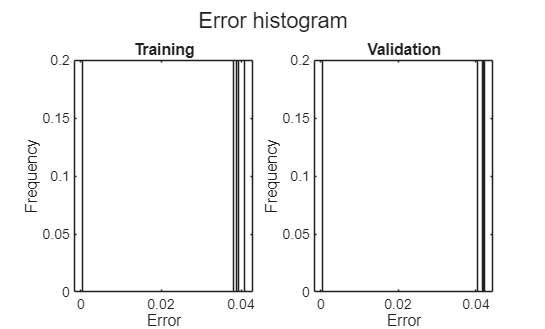

Y_tr_pred = extractdata(FFnet.predict(dlX_tr));
Y_val_pred = extractdata(FFnet.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

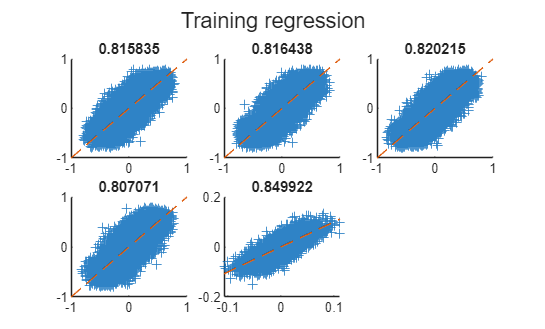

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

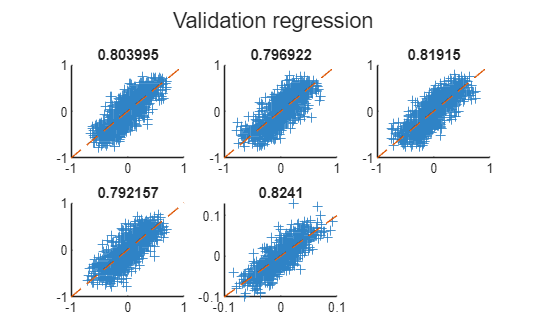


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = FFnet.Learnables

Learnables = 6×3 table
       Layer       Parameter         Value     
    ___________    _________    _______________

    "fc_1"         "Weights"    {66×22 dlarray}
    "fc_1"         "Bias"       {66×1  dlarray}
    "batchnorm"    "Offset"     {66×1  dlarray}
    "batchnorm"    "Scale"      {66×1  dlarray}
    "fc_2"         "Weights"    { 5×66 dlarray}
    "fc_2"         "Bias"       { 5×1  dlarray}


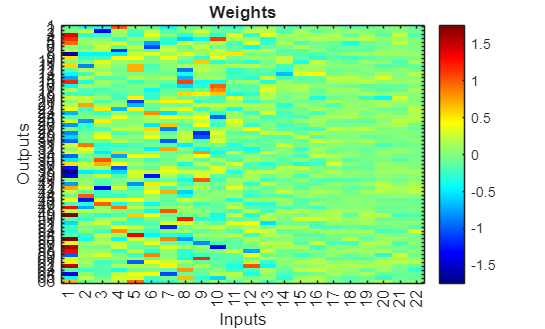

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = 0.0176

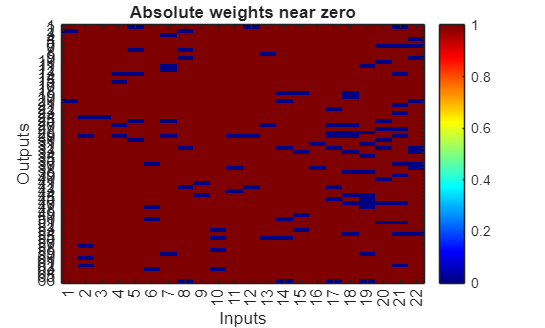

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));